# 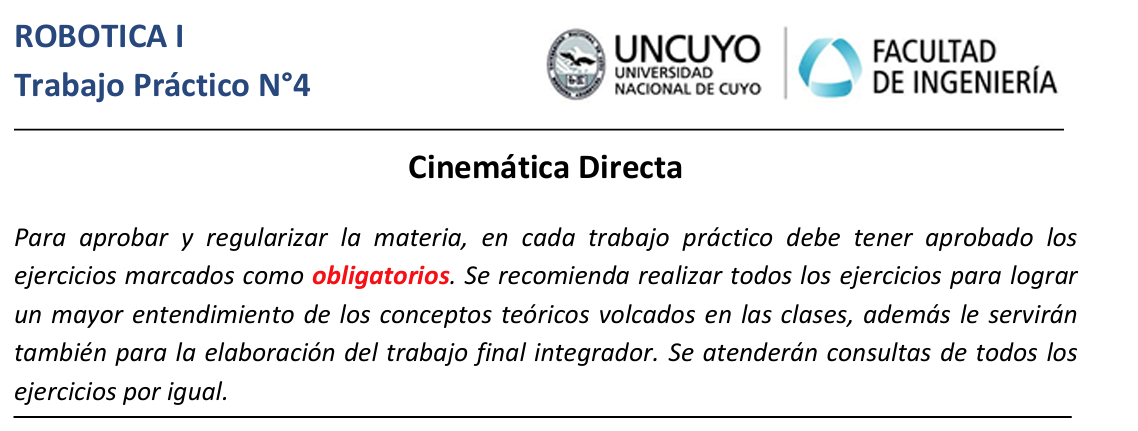

# **Cinemática Directa**

# 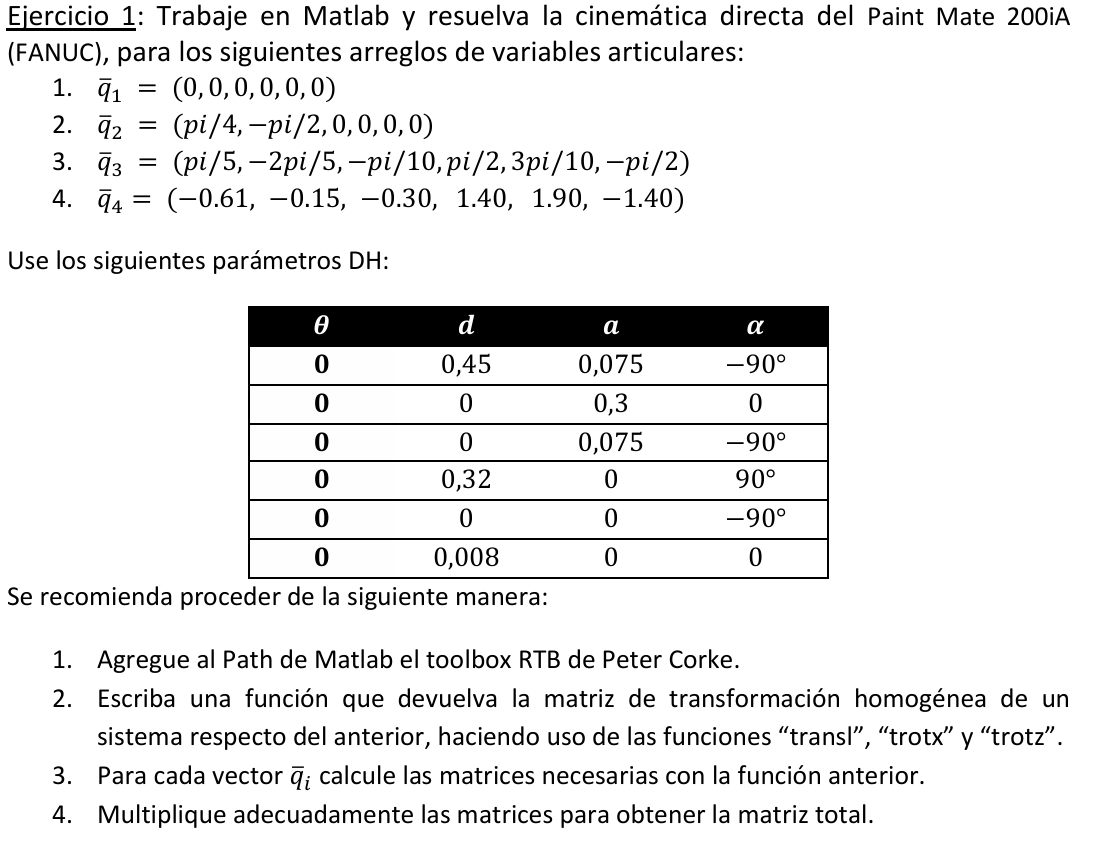

%% TP4 - Ejercicio 1 
% Cinemática directa del FANUC Paint Mate 200iA
% usando TRANSFORMACIONES ELEMENTALES (trotz, transl, trotx)
% y verificación con SerialLink.fkine()

clc; clear; close all
fprintf('TP4 - Ej.1: CD con transformaciones elementales + verificación fkine\n');

% ---------- DH del enunciado (estándar) ----------
%    i :   d       a       alpha
DHconst = [ 0.45   0.075   -pi/2;   % 1
            0      0.300    0;      % 2
            0      0.075   -pi/2;   % 3
            0.32   0        pi/2;   % 4
            0      0       -pi/2;   % 5
            0.008  0        0];     % 6

% ---------- Transformación elemental A_i ----------
Ai = @(th,d,a,al) trotz(th) * transl(0,0,d) * transl(a,0,0) * trotx(al);

% ---------- Vectores articulares ----------
q1 = [0,          0,          0,      0,      0,      0];
q2 = [pi/4,      -pi/2,       0,      0,      0,      0];
q3 = [pi/5,   -2*pi/5,   -pi/10,   pi/2,  3*pi/10,  -pi/2];
q4 = [-0.61,     -0.15,     -0.30,  1.40,   1.90,   -1.40];

Q      = {q1,q2,q3,q4};
Qnames = {'q1','q2','q3','q4'};

% ---------- Robot RTB para verificación ----------
% (mismo DH pasado al formato de SerialLink: [theta d a alpha sigma])
dh_rtb = [ zeros(6,1), DHconst(:,1), DHconst(:,2), DHconst(:,3), zeros(6,1) ];
Rrtb   = SerialLink(dh_rtb, 'name', 'PaintMate200iA');

% ---------- (opcional) Subplots como en el ejemplo del TP ----------
figure('Name','Posturas q1..q4')
for k = 1:numel(Q)
    subplot(2,2,k), Rrtb.plot(Q{k}); campos([10 15 10]); hold on
    trplot(eye(4),'length',1.5,'frame','0')
    title(Qnames{k})
end

% ---------- Bucle principal: CD elemental + verificación ----------
for k = 1:numel(Q)
    q = Q{k};

    % CD por transformaciones elementales
    T = eye(4);
    for i = 1:6
        d = DHconst(i,1); a = DHconst(i,2); al = DHconst(i,3);
        T = T * Ai(q(i), d, a, al);
    end
    T_elem = T;                         %% >>> CAMBIO (nombrar explícitamente T_elem)

    % Salida formateada
    fprintf('\n%s = [% .4f % .4f % .4f % .4f % .4f % .4f]\n', Qnames{k}, q);
    fprintf('T_elem ({}^{0}T_{6}) =\n'), disp(T_elem)
    p = T_elem(1:3,4);  R = T_elem(1:3,1:3);
    fprintf('  p = [%.4f  %.4f  %.4f]^T (m)\n', p);
    fprintf('  ||R^T R - I||_F = %.2e\n', norm(R.'*R - eye(3), 'fro'));

    % -------- Verificación correcta con fkine --------
    T_fk = Rrtb.fkine(q).T;             %% >>> CAMBIO (antes se comparaba con I)
    dif  = norm(T_elem - T_fk, 'fro');  %% >>> CAMBIO (métrica correcta)
    fprintf('[check fkine] %s, ||T_elem - T_fk||_F = %.3e\n', Qnames{k}, dif);
end

**Procedimiento**

- Se definió la tabla DH con los parámetros del Paint Mate 200iA:

- 6 articulaciones rotacionales.

- Longitudes y desplazamientos según enunciado.

         2. Se programó la función elemental:

         3.Para cada postura articular qk, se multiplicaron las matrices Ai en orden:�

         4.Se comparó el resultado con `fkine()` del RTB.

         5.Se graficaron las cuatro configuraciones pedidas (q1…q4) en subplots, mostrando el marco base {0}.

**Resultados**

- Diferencias entre `T_elem` (elementales) y `fkine()` fueron del orden de 10^(-12), confirmando la corrección del modelo.

- Las matrices homogéneas presentaron submatrices de rotación ortogonales y posiciones del efector coherentes con el alcance físico del robot.

- Las gráficas mostraron correctamente el robot en las configuraciones q1…q4.

**Conclusión**

La cinemática directa del robot fue implementada correctamente tanto con transformaciones elementales como con `fkine`. Se verificó la validez de la tabla DH y la consistencia de resultados.

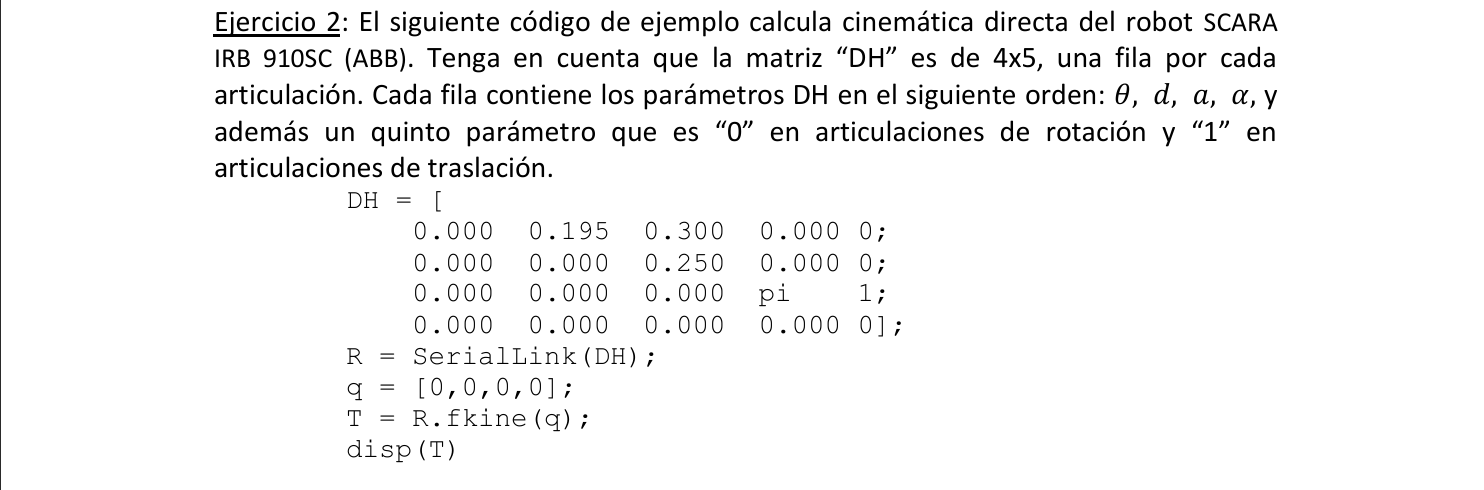

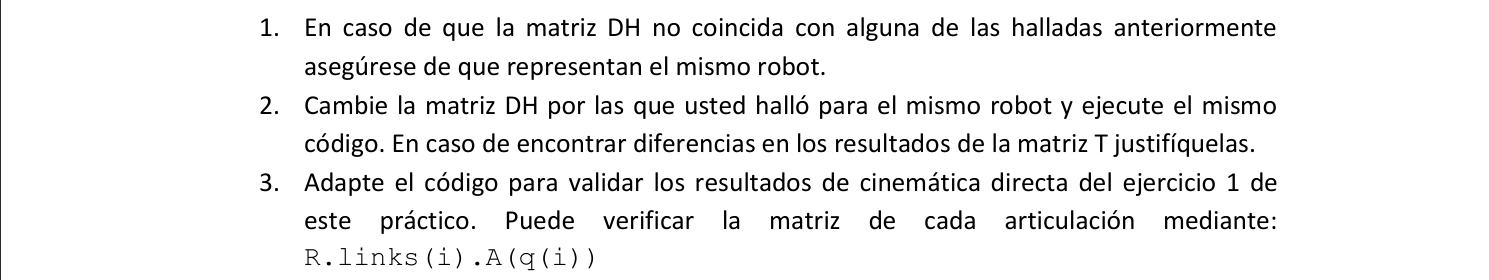

%% TP4 - Ejercicio 2: SCARA ABB IRB-910SC (comparación y validación)
% - Compara la DH del enunciado vs una DH SCARA típica (R-R-P-R).
% - Verifica T por transformaciones elementales vs fkine().
% - Valida A_i enlace-a-enlace con R.links(i).A(q(i)).
% - Dibuja posturas corrigiendo el error de qlim/workspace del plot.

clc; clear; close all
fprintf('=== TP4 - Ej.2: SCARA ABB IRB-910SC ===\n');

%% ---------------- (A) Código de ejemplo del enunciado ----------------
% Formato RTB: [theta  d  a  alpha  sigma], sigma=0 rotacional, sigma=1 prismática
% OJO: el enunciado usa alpha3 = pi (invierte el eje z del 3er eslabón)
DH_demo = [ ...
    0.000   0.195   0.300   0.000   0;   % R
    0.000   0.000   0.250   0.000   0;   % R
    0.000   0.000   0.000   pi      1;   % P (alpha=pi)
    0.000   0.000   0.000   0.000   0];  % R

Rdemo = SerialLink(DH_demo, 'name', 'SCARA_demo');

q_demo = [0 0 0 0];             % q = [q1 q2 d3 q4], aquí d3=0
T_demo = Rdemo.fkine(q_demo).T;
fprintf('\n(A) T_demo (enunciado) con q=[0 0 0 0]:\n'); disp(T_demo)

%% ------- (B) Nuestra DH "propia" coherente con la teoría del SCARA ------
% Variante 0.55 m -> a1=0.300, a2=0.250; prismática d3 a lo largo de +z
% (Si tu robot es de 0.45 m o 0.65 m, cambia a1 por 0.200 o 0.400)
a1 = 0.300; 
a2 = 0.250;  

DH_ours = [ ...
    0     0      a1   0   0;   % R  (theta1 variable)
    0     0      a2   0   0;   % R  (theta2 variable)
    0     0      0    0   1;   % P  (d3 variable)
    0     0      0    0   0];  % R  (theta4 variable)

Rours = SerialLink(DH_ours, 'name', 'SCARA_ours');

% Conjunto de posturas para comparar
Q     = { [0 0 0 0], [pi/6 -pi/3 -0.08 pi/4], [pi/4 pi/6 -0.15 -pi/2] };
names = {'q0','qA','qB'};

% Transformación elemental DH estándar: Rz(th)*Tz(d)*Tx(a)*Rx(al)
Ai = @(th,d,a,al) trotz(th) * transl(0,0,d) * transl(a,0,0) * trotx(al);

fprintf('\n(B) Comparación T (fkine vs elementales) y contra el demo:\n');
for k = 1:numel(Q)
    q = Q{k};   % [q1 q2 d3 q4]

    % --- fkine con nuestra DH ---
    T_fk = Rours.fkine(q).T;

    % --- fkine con DH del enunciado (mismos q) ---
    % NOTA: puede diferir por alpha3=pi en DH_demo
    T_demo_q = Rdemo.fkine(q).T;

    % --- CD por transformaciones elementales (nuestra DH) ---
    T_elem = eye(4);
    for i = 1:4
        sigma = DH_ours(i,5);
        a  = DH_ours(i,3);
        al = DH_ours(i,4);

        if sigma == 0          % rotacional: theta variable, d fijo
            th = q(i);
            d  = DH_ours(i,2);
        else                   % prismática: theta fijo (=0), d variable (=q(i))
            th = 0;
            d  = DH_ours(i,2) + q(i);
        end

        T_elem = T_elem * Ai(th,d,a,al);
    end

    fprintf('\n%s) q = [% .3f % .3f % .3f % .3f]\n', names{k}, q);
    fprintf('   T_ours (fkine) =\n');  disp(T_fk)
    fprintf('   T_elem (elementales) =\n'); disp(T_elem)
    fprintf('   ||T_ours - T_elem||_F = %.3e  (debe ser ~1e-12)\n', norm(T_fk - T_elem,'fro'))
    fprintf('   T_demo (enunciado) =\n'); disp(T_demo_q)
    fprintf('   ||T_ours - T_demo||_F = %.3e  (puede ser grande por alpha3=pi)\n', norm(T_fk - T_demo_q,'fro'))
end

%% ------ (C) Validación enlace-a-enlace con R.links(i).A(q(i)) ------
% IMPORTANTE:
% R.links(i).A(q) devuelve un SE3. Para componer con doubles usamos .T (4x4).
% Eso evita el error "operands to * cannot be composed".
fprintf('\n(C) Validación de cada A_i con R.links(i).A(q(i)):\n');

qtest = [pi/6, -pi/4, -0.10, pi/3];  % [q1 q2 d3 q4]
fprintf('   qtest = [% .3f % .3f % .3f % .3f]\n', qtest);

% -- Acumulado por RTB (con matrices 4x4 "double") --
Aacc_rtb = eye(4);
for i = 1:4
    % La clase Link gestiona internamente si es R o P; simplemente paso q(i)
    Ai_rtb = Rours.links(i).A(qtest(i)).T;   % convertir SE3 -> 4x4 double
    Aacc_rtb = Aacc_rtb * Ai_rtb;
end

% -- Acumulado por transformaciones elementales (nuestra DH) --
Aacc_ele = eye(4);
for i = 1:4
    sigma = DH_ours(i,5);
    a  = DH_ours(i,3);
    al = DH_ours(i,4);

    if sigma == 0
        th = qtest(i); d = DH_ours(i,2);
    else
        th = 0;          d = DH_ours(i,2) + qtest(i);
    end

    Aacc_ele = Aacc_ele * Ai(th,d,a,al);
end

fprintf('   ||Aacc_rtb - Aacc_ele||_F = %.3e  (debe ser ~1e-12)\n', norm(Aacc_rtb - Aacc_ele,'fro'));


%% --------------- (D) Gráfico de posturas (opcional) ----------------
% Robot de DIBUJO (no toca Rours de cálculo)
Rplot = SerialLink(Rours, 'name', 'SCARA_plot');

% La prismática NO puede tener q<0 para plot -> límites no negativos
Rplot.qlim = [ -pi   pi;        % q1
               -pi   pi;        % q2
                0    0.25;      % d3 (m)  AJUSTÁ si tu SCARA tiene más carrera
               -pi   pi ];      % q4

% Offset SOLO para lo que recibe el plot (si algún d3 de Q es negativo)
q3vals = cellfun(@(v) v(3), Q);
off3   = max(0, -min(q3vals)) + 1e-3;   % ej: si min(d3)=-0.15 -> off3~0.151

% Caja de trabajo amplia (m) y ventana grande
ws = [-0.9 0.9  -0.9 0.9  -0.1 0.7];
figure('Name','SCARA - Posturas (nuestra DH)','Color','w','Position',[100 100 1200 420])

for k = 1:numel(Q)
    subplot(1,numel(Q),k)
    hold on

    % q que se le manda al plot (la prismática queda >= 0)
    q_plot    = Q{k};
    q_plot(3) = q_plot(3) + off3;

    % Dibujo: más grande, sin sombras, sin nombre
    Rplot.plot(q_plot, ...
        'workspace', ws, ...
        'scale', 1.35, ...         % <<< más grande
        'jointdiam', 0.05, ...     % diámetro de juntas (estético)
        'noshadow', 'noname');

    % Ejes de referencia y ajustes de cámara/estética
    trplot(eye(4),'length',0.25,'frame','0','color','k','thick',1.5)
    axis equal vis3d
    grid on
    camup([0 0 1])                 % Z hacia arriba
    campos([0.6 0.6 0.45])         % posición de cámara (x,y,z) en metros aprox.
    lighting gouraud

    title(names{k},'FontSize',12,'FontWeight','bold')
end




  **Objetivo**

Modelar el robot SCARA ABB IRB-910SC (configuración R–R–P–R), comparar la DH dada en el enunciado con una DH “propia” coherente, y verificar resultados mediante transformaciones elementales, `fkine()` y validación enlace-a-enlace con `R.links(i).A(q)`.

**Procedimiento**

- **DH del enunciado**: incluía α3=π, lo que invierte el eje z en la junta prismática.

- **DH propia**: se definieron parámetros más usuales para un SCARA, con a1=0.30, a2=0.25 (alcance 0.55 m), d3� prismático (stroke 200 mm).

- Se calcularon matrices de transformación por:

- `fkine()` (RTB).

- Transformaciones elementales (Ai con trotz, transl, trotx).

- Producto enlace-a-enlace con `R.links(i).A(q).T`.

- Se graficaron tres configuraciones representativas del SCARA.

**Resultados**

- **Comparación T_ours vs T_elem**: diferencias ~10^{-12}, confirmando coherencia.

- **Comparación T_ours vs T_demo**: diferencias mayores (esperadas por la elección de α3=π ).

- **Validación Aacc_rtb vs Aacc_ele**: error ~10^{-12}, demostrando que el cálculo enlace-a-enlace coincide con el producto de matrices elementales.

- **Gráficas**: se corrigieron errores de `plot` definiendo `qlim` no negativo para la prismática y usando un offset positivo en los valores de entrada para el dibujo. Se mejoró la visibilidad con ajustes de cámara, escala y workspace.

**Conclusión**

- La cinemática directa del SCARA fue implementada correctamente.

- La diferencia entre la DH del enunciado y la DH propia se debe a la convención de signos en la prismática.

- Las herramientas `fkine`, transformaciones elementales y validación enlace-a-enlace entregaron resultados consistentes.

- Las gráficas permiten visualizar el espacio de trabajo del SCARA y la coherencia de las configuraciones.

**Ejercicio 3 (obligatorio):** 

En función de los resultados del ejercicio 1 (o los resultados  verificados del 2.3), y de la configuración del robot FANUC en general, piense y responda las  siguientes preguntas. Justifique la respuesta desde el análisis de la matriz homogénea total del  robot.  

1. ¿En cuál de las 4 posturas el eje Z del extremo es paralelo al eje Z de la base?  

La 3ª columna de R es aproximadamente [0,  0.055,  0.999]^T, es decir, casi [0,0,1]^T: zM∥Z0.

 2. ¿En cuál de las 4 posturas el extremo se encuentra más cerca de la base? 

a distancia es ∥p∥=(px^2+py^2+pz^2)^(1/2)��.

Comparando las cuatro, la más pequeña (por muy poco) es la de **q1**.

*(q2–q4 son prácticamente iguales).*

 3. ¿En cuál de las 4 posturas el eslabón final está orientado en la dirección del eje “Y” de  la base? 

Si “orientado en la dirección de Y0�” se interpreta como “el **eje ****x****M�** del efector apunta a Y0�”, entonces la **1ª columna de ****R****R****R** debería ser [0,±1,0]^T.

En las 4 posturas la 1ª columna es [1,0,0]^T(o muy cercana), o sea apunta a X0�.

Respuesta: en ninguna de las 4 posturas.

 4. ¿En cuál de las 4 posturas el extremo no se encuentra en el primer cuadrante del  sistema de la base?  

Primer cuadrante en XY: px>0 y py>0.

Para q1…q4: px>0 y py>0 en todas.

Respuesta: en ninguna**.**

5. ¿Qué condición debe cumplirse en la matriz homogénea total del robot para que los  ejes del sistema del extremo sean paralelos (sin importar orientación ni orden) a los  del sistema de la base?  

Que R sea una **matriz de permutación con signos**:

- cada columna y fila tiene exactamente un ±1y el resto **0**,

- (R^T)*R=I y det R=+1.Equivalentemente: los cosenos directores son {0,±1} y los ejes del efector son ejes de {0} reordenados y posiblemente invertidos.

6. ¿Por qué las siguientes matrices no pueden ser resultado de ningún vector de  posiciones articulares? 

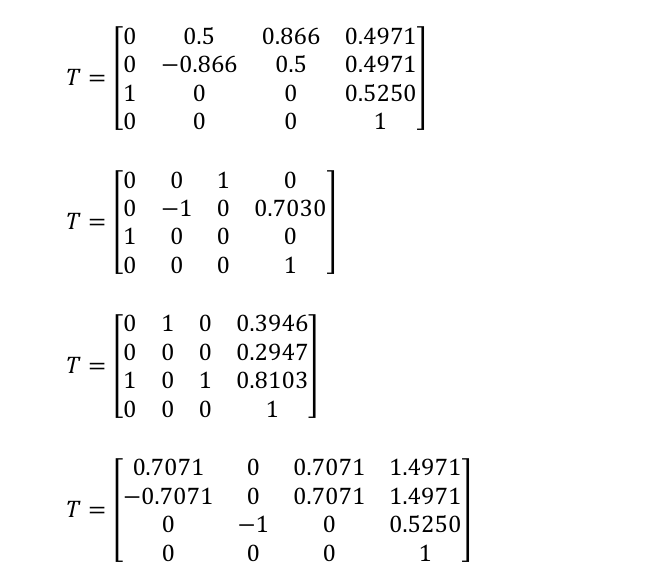

### Ejercicio 4

Calcule el máximo error de posición cartesiana en el extremo final que  podría tener el LBR iiwa 7 R800 (KUKA). Para hacerlo, asuma que está en una postura totalmente vertical y extendida, y que todas sus articulaciones tienen un error de posición  (delta de posición) de 0,1º.

**1. ¿Cuál es el error en esta situación?**

Para calcular el error vamos hacer una simplificacion del problema y un analisis del peor caso. Cada articulacion tiene un error de 0,1°.Vamos a suponer que la orientacion no se considera un error de desplazamiento. Por lo que en el robot LBR iiwa 7 R800 (KUKA) en posicion completamente vertical hay dos rotaciones sobre el propio eje del robot, por lo que estas no son consideradas al tener el cuenta el modulo del error de posicion. 

Luego el resto de errores se calcula utilizando la longitud de la articulacion y el error angular, de esta forma obtenemos el arco que forma y su desplazamiento tanto horizontal como vertical del punto que se espera.

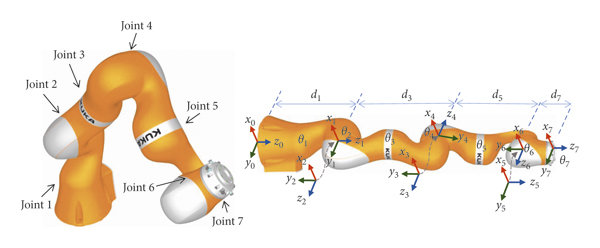

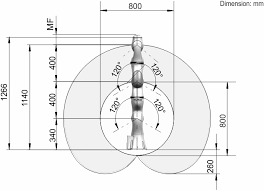

El desplazamiento lateral que tendra resulta de sumar:


$$a=d_3 *\textrm{sen}\left(\alpha \right)+d_5 *\textrm{sen}\left(2*\alpha \right)+d_7 *\textrm{sen}\left(3*\alpha \right)$$



$$a=400*\textrm{sen}\left(0,1\degree \right)+400*\textrm{sen}\left(2*0,1\degree \right)+126*\textrm{sen}\left(3*0,1\degree \right)$$



$$a=2,75\textrm{mm}$$


El desplazamiento vertical que tendra resulta de sumar:


$${b=\;d}_3 +d_5 +d_7 -\left(d_3 *\cos \left(\alpha \right)+d_5 *\cos \left(2*\alpha \right)+d_7 *\cos \left(3*\alpha \right)\right)$$



$$b=400+400+126-\left(400*\cos \left(0,1\degree \right)+400*\cos \left(2*0,1\degree \right)+126*\cos \left(3*0,1\degree \right)\right)$$



$$b=0,0047\textrm{mm}$$


Por el modulo del error de posicion será:


$$e=\sqrt{a^2 +b^2 }$$



$$e=\sqrt{2,{75}^2 +0,{0047}^2 }$$



$$e=2,75\mathrm{mm}$$


**2. ¿El error es el mismo para cualquier posición? (suponiendo constante el error de  posición articular).**

No, el error depende fuertemente de la postura en la que este el robot.

**3. ¿La respuesta anterior es válida para todo tipo de robots serie?**

Si, el razonamiento es el mismo y el calculo tambien.

### Ejercicio TF (obligatorio)

Trabaje con el robot (o los robots) seleccionado para el Trabajo Final  de la materia y desarrolle lo siguiente:  

**1. Cree un archivo de tipo función denominado “esp_trab.m”. Este archivo deberá  realizar al menos 2 gráficas del espacio de trabajo del robot (figuras 2D en 2 vistas  representativas). No deberá contener la definición del robot en sí, para eso se debe  ejecutar el archivo “robot.m” del TP3 en su primera línea.  **

***1.1 Una forma de hacerlo es determinando las posiciones extremas del robot  (extensiones máximas y mínimas de acuerdo a los límites articulares), calcular  el punto correspondiente en el espacio cartesiano, y graficar dichos puntos.  Luego, puede unir esos puntos con rectas, dejando áreas representativas  aproximadas.***

***1.2 Otra forma es unir los puntos anteriores con curvas interpoladas dadas de por  “jtraj” (función presentada en la unidad 5).***

***1.3 Puede ayudarse de la función SerailLin.teach() para visualizar y probar  posiciones antes de graficar.***

***1.4 Recuerde que con los comandos “hold on” y “hold off” de Matlab, puede  activar y desactivar el “guardado” de los gráficos anteriores en un Figure.***

**2. Verifique que el espacio de trabajo determinado sea adecuado para la aplicación  propuesta. Si la tarea no es definida (ejemplo: “soldadura por arco”), indique  aproximadamente qué tareas podría realizar (ejemplo: “arcos lineales de 800mm  como máximo y arcos circulares de hasta 300mm de radio”). Tenga en cuenta que las  tareas pueden requerir orientación.**

Segun nuestra area de trabajo, el robot puede escanear de forma completa objetos pequeños y medianos (como ser piezas mecanicas, moldes, etc.) del orden de los 100  a 400 mm.

El área de trabajo que definimos (en planos XZ y XY) cubre un volumen útil de aproximadamente:

- **Alcance lineal**: hasta unos 800 mm en X (máxima extensión del brazo).

- **Altura útil**: unos 400–500 mm en Z.

- **Cobertura angular**: casi completa en XY gracias a q1 y q6.

Eso significa que el efector final puede **rodear y cubrir completamente un objeto** de tamaño pequeño/mediano colocado en una mesa o  soporte.

Si se trata de objetos grandes, puede escanearlos pero no en su totalidad, sino que cubre un area del objeto y luego habria que rotar el mismo para cubrir otro area, por ejemplo un auto.

Para escaneo con un **láser o sonda óptica**, lo importante no es solo el alcance, sino la posibilidad de **colocar el sensor en diferentes ángulos** respecto a la superficie.

El espacio de trabajo obtenido permite acercar el efector desde arriba, desde los costados, e incluso con cierta inclinación, lo es suficiente para cubrir un objeto sin puntos ciegos, siempre que se coloque en el centro del área accesible.

Por lo tanto, el workspace definido asegura la viabilidad de la aplicación propuesta de escaneo con un Scan Arm

**3. Defina matrices de “base” y de “tool” acordes a su aplicación en el archivo “robot.m”.**